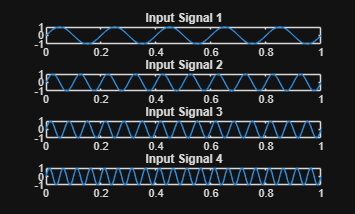

clc;
clear;
close all;

%% Parameters
fs = 1000;              % Sampling frequency
t = 0:1/fs:1;           % Time vector

%% Input Signals
x1 = sin(2*pi*5*t);     % Signal 1
x2 = sin(2*pi*10*t);    % Signal 2
x3 = sin(2*pi*15*t);    % Signal 3
x4 = sin(2*pi*20*t);    % Signal 4

%% TDM Multiplexing
tdm_signal = zeros(1,4*length(t));

tdm_signal(1:4:end) = x1;
tdm_signal(2:4:end) = x2;
tdm_signal(3:4:end) = x3;
tdm_signal(4:4:end) = x4;

t_tdm = linspace(0,1,length(tdm_signal));

%% Demultiplexing
rx1 = tdm_signal(1:4:end);
rx2 = tdm_signal(2:4:end);
rx3 = tdm_signal(3:4:end);
rx4 = tdm_signal(4:4:end);

%% Plot Input Signals
figure
subplot(4,1,1); plot(t,x1); title('Input Signal 1');
subplot(4,1,2); plot(t,x2); title('Input Signal 2');
subplot(4,1,3); plot(t,x3); title('Input Signal 3');
subplot(4,1,4); plot(t,x4); title('Input Signal 4');

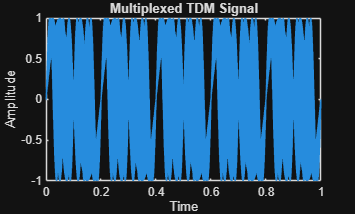


%% Plot TDM Signal
figure
plot(t_tdm,tdm_signal)
title('Multiplexed TDM Signal')
xlabel('Time')
ylabel('Amplitude')

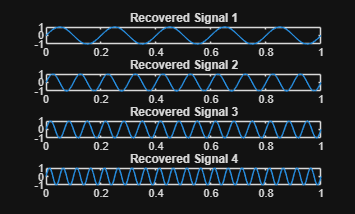


%% Plot Recovered Signals
figure
subplot(4,1,1); plot(t,rx1); title('Recovered Signal 1');
subplot(4,1,2); plot(t,rx2); title('Recovered Signal 2');
subplot(4,1,3); plot(t,rx3); title('Recovered Signal 3');
subplot(4,1,4); plot(t,rx4); title('Recovered Signal 4');